Question: 1

clear;
load("data1.mat");
iter = 500000;

% Prior of estimates
theta1 = 2.*randn(iter,1) + 0.8;
theta2 = 2.*randn(iter,1) + 99;
x1_0   = 2.*randn(iter,1) + 2;

% Posterior of estimates
posterior = [];

% Monte-carlo simulation
for i = 1:iter
    
    t1 = theta1(i,1);
    t2 = theta2(i,1);
    x0 = x1_0(i,1);
    
    A = [-t1 0; t1 -t2];
    Ad = expm(A);
    Bd = [0; 0];
    C = [1 1];
    D = 0;
    
    x_k = [x0; 2];
    error = 0;
    error = error + abs(C * x_k - yt(1));
    for j = 2:length(yt)
        x_kplus1 = Ad * x_k;
        error = error + abs(C * x_kplus1 - yt(j));
        x_k = x_kplus1;
    end
    
    error = error / length(yt);
    if error < 0.06
        posterior = [posterior; [t1 t2 x0]];
    end
end

% Jointly gaussian + uncorrelated = independent
corr(posterior)

ans =     1.0000    0.0199    0.6067
    0.0199    1.0000    0.0110
    0.6067    0.0110    1.0000


length(posterior)

ans = 2657

mean(posterior)

ans =     0.1366   98.9858    1.1994


est_parama_std = sqrt(var(posterior))

est_parama_std =     0.0458    2.0358    0.3542


Question: 2

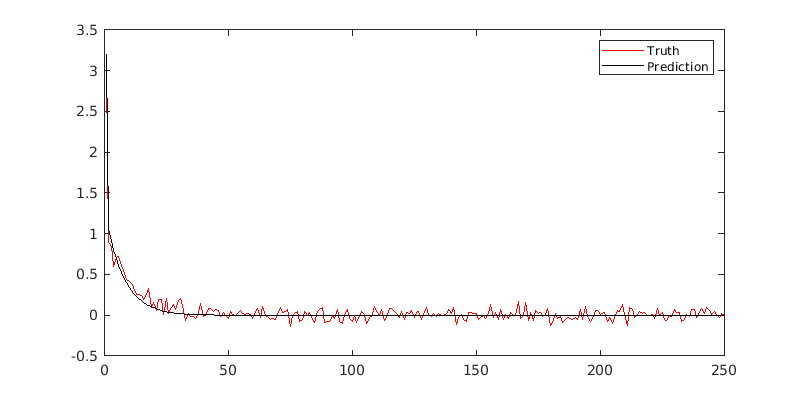

params_est = mean(posterior);

A = [-params_est(1) 0; params_est(1) -params_est(2)];
Ad = expm(A);
Bd = [0; 0];
C = [1 1];
D = 0;
    
x_k = [params_est(3); 2];
yhat = [C * x_k];
for j = 2:length(yt)
    x_kplus1 = Ad * x_k;
    yhat = [yhat ; C * x_kplus1];
    x_k = x_kplus1;
end

figure;set(gcf,'position',[10,10,800,400]);
plot(yt,'red'); hold on; plot(yhat,'black');
legend('Truth','Prediction');
xlim([0 length(yt)-1]);

Question: 3

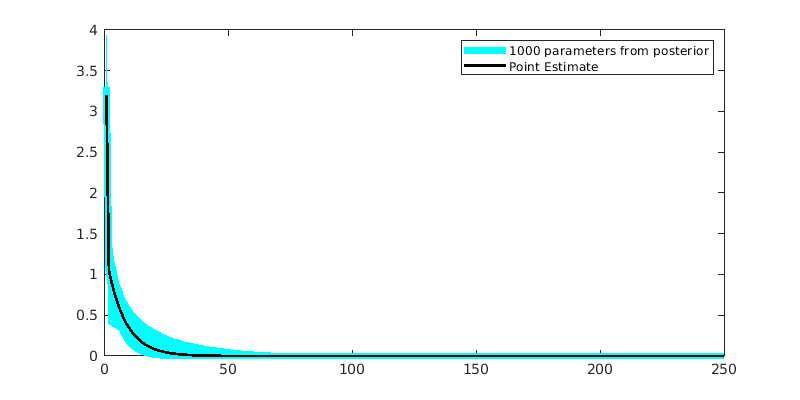

rand_index = randperm(length(posterior), 1000);

figure;set(gcf,'position',[10,10,800,400]);
for i = 1:1000

    A = [-posterior(rand_index(i), 1) 0; posterior(rand_index(i), 1) -posterior(rand_index(i), 2)];
    Ad = expm(A);
    Bd = [0; 0];
    C = [1 1];
    D = 0;
        
    x_k = [posterior(rand_index(i), 3); 2];
    yhat_1000 = [C * x_k];
    for j = 2:length(yt)
        x_kplus1 = Ad * x_k;
        yhat_1000 = [yhat_1000 ; C * x_kplus1];
        x_k = x_kplus1;
    end
    
    if (i~=1)
       g = plot(yhat_1000,'cyan'); hold on;
       g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
    else
        plot(yhat_1000,'cyan','LineWidth',5); hold on;
    end
end

plot(yhat,'black','LineWidth',2);
legend({'1000 parameters from posterior','Point Estimate'});
xlim([0 length(yt)-1]);

Question: 4

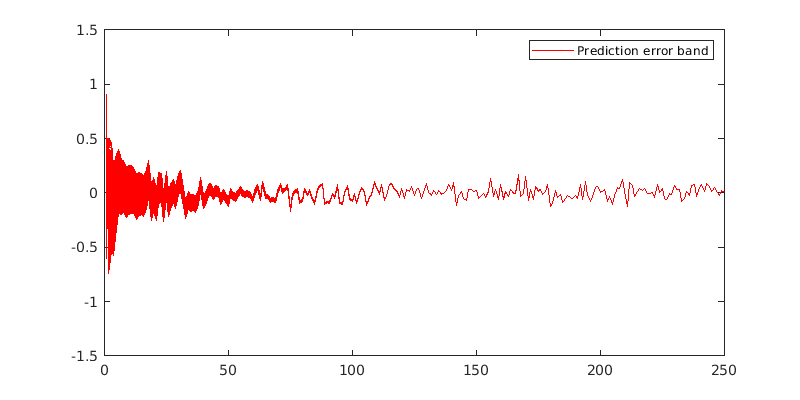

figure;set(gcf,'position',[10,10,800,400]);
ERROR = [];
for i = 1:1000

    A = [-posterior(rand_index(i), 1) 0; posterior(rand_index(i), 1) -posterior(rand_index(i), 2)];
    Ad = expm(A);
    Bd = [0; 0];
    C = [1 1];
    D = 0;
        
    x_k = [posterior(rand_index(i), 3); 2];
    error = [C * x_k - yt(1)];
    for j = 2:length(yt)
        x_kplus1 = Ad * x_k;
        error = [error ; yt(j) - (C * x_kplus1)];
        x_k = x_kplus1;
    end
    
    ERROR = [ERROR error];
    if (i~=1)
       g = plot(error,'red'); hold on;
       g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
    else
        plot(error,'red'); hold on;
    end
end

legend('Prediction error band');
xlim([0 length(yt)-1]);
ylim([-1.5 1.5]);

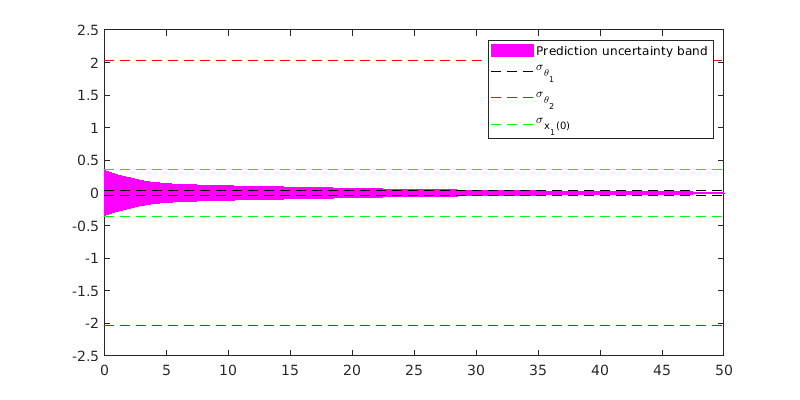

figure;set(gcf,'position',[10,10,800,400]);

% Shaded region
x = 0 : length(yt) -1;
curve1 = std(transpose(ERROR));
curve2 = -1*std(transpose(ERROR));
g = plot(x, curve1, 'm'); hold on;
g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
g = plot(x, curve2, 'm'); hold on;
g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
x2 = [x, fliplr(x)];
inBetween = [curve1, fliplr(curve2)];
fill(x2, inBetween, 'm', 'EdgeColor','m');

% Dotted lines
est_parama_std = sqrt(var(posterior));

plot([0 length(yt)] ,[1 1]* est_parama_std(1) ,'black--'); hold on;
g = plot([0 length(yt)] ,[-1 -1]* est_parama_std(1) ,'black--');
g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 

plot([0 length(yt)] ,[1 1]*est_parama_std(2) ,'r--')
g = plot([0 length(yt)] ,[-1 -1]*est_parama_std(2) ,'r--');
g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 

plot([0 length(yt)] ,[1 1]*est_parama_std(3) ,'g--');
g = plot([0 length(yt)] ,[-1 -1]*est_parama_std(3) ,'g--');
g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 

legend('Prediction uncertainty band','\sigma_{\theta_1}','\sigma_{\theta_2}','\sigma_{x_1(0)}');
xlim([0 50]);

Question 5:

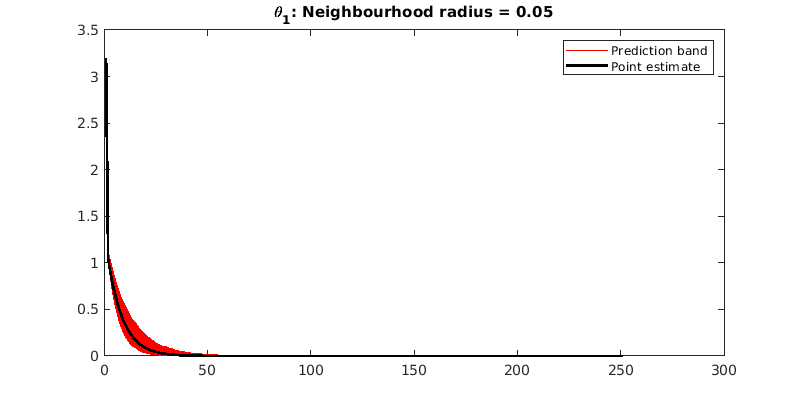

params_est = mean(posterior);

% Generate random neighbouring points:
iter = 1000;
radius = 0.05;

theta1 = -radius + (2*radius).*rand(iter,1) + params_est(1);

figure;set(gcf,'position',[10,10,800,400]);
for i = 1:iter

    A = [-theta1(i) 0; theta1(i) -params_est(2)];
    Ad = expm(A);
    Bd = [0; 0];
    C = [1 1];
    D = 0;
        
    x_k = [params_est(3); 2];
    yhat_neighbors = [C * x_k];
    for j = 2:length(yt)
        x_kplus1 = Ad * x_k;
        yhat_neighbors = [yhat_neighbors ; (C * x_kplus1)];
        x_k = x_kplus1;
    end
    
    if (i~=1)
       g = plot(yhat_neighbors,'red'); hold on;
       g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
    else
        plot(yhat_neighbors,'red','LineWidth',1); hold on;
    end
end
plot(yhat,'black','LineWidth',2);
legend('Prediction band','Point estimate');
title('\theta_1: Neighbourhood radius = 0.05');

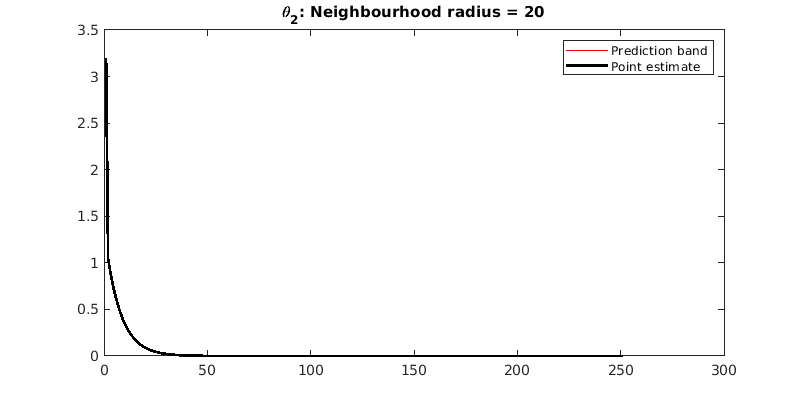

% Generate random neighbouring points:
iter = 1000;
radius = 20;

theta2 = -radius + (2*radius).*rand(iter,1) + params_est(2);

figure;set(gcf,'position',[10,10,800,400]);
for i = 1:iter

    A = [-params_est(1) 0; params_est(1) -theta2(i)];
    Ad = expm(A);
    Bd = [0; 0];
    C = [1 1];
    D = 0;
        
    x_k = [params_est(3); 2];
    yhat_neighbors = [C * x_k];
    for j = 2:length(yt)
        x_kplus1 = Ad * x_k;
        yhat_neighbors = [yhat_neighbors ; (C * x_kplus1)];
        x_k = x_kplus1;
    end
    
    if (i~=1)
       g = plot(yhat_neighbors,'red'); hold on;
       g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
    else
        plot(yhat_neighbors,'red','LineWidth',1); hold on;
    end
end
plot(yhat,'black','LineWidth',2);
legend('Prediction band','Point estimate');
title('\theta_2: Neighbourhood radius = 20');

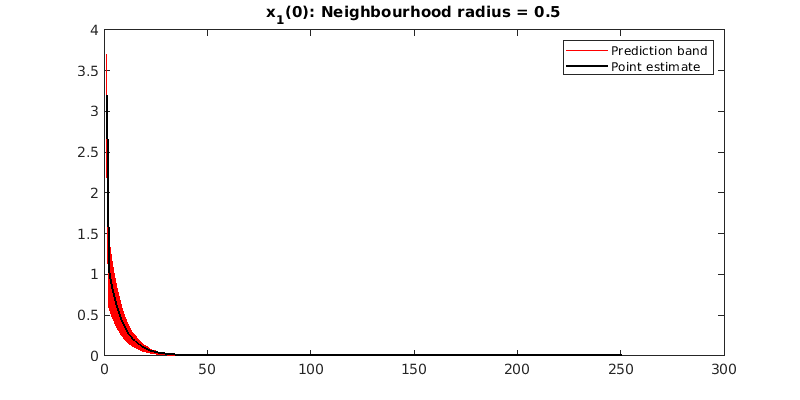

% Generate random neighbouring points:
iter = 1000;
radius = 0.5;

x1 = -radius + (2*radius).*rand(iter,1) + params_est(3);

figure;set(gcf,'position',[10,10,800,400]);
for i = 1:iter

    A = [-params_est(1) 0; params_est(1) -params_est(2)];
    Ad = expm(A);
    Bd = [0; 0];
    C = [1 1];
    D = 0;
        
    x_k = [x1(i); 2];
    yhat_neighbors = [C * x_k];
    for j = 2:length(yt)
        x_kplus1 = Ad * x_k;
        yhat_neighbors = [yhat_neighbors ; (C * x_kplus1)];
        x_k = x_kplus1;
    end
    
    if (i~=1)
       g = plot(yhat_neighbors,'red'); hold on;
       g.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
    else
        plot(yhat_neighbors,'red','LineWidth',1); hold on;
    end
end
plot(yhat,'black','LineWidth',1.5);
legend('Prediction band','Point estimate');
title('x_1(0): Neighbourhood radius = 0.5');

syms theta_1 theta_2 x_1 k;
A = [-theta_1 0; theta_1 -theta_2];
Ad = expm(A)

$$Ad = \left(\begin{array}{cc} {\mathrm{e}}^{-\theta_{1}} & 0\\ -\frac{\theta_{1}\,{\mathrm{e}}^{-\theta_{1}}-\theta_{1}\,{\mathrm{e}}^{-\theta_{2}}}{\theta_{1}-\theta_{2}} & {\mathrm{e}}^{-\theta_{2}} \end{array}\right)$$

C = [1 1]

C =      1     1


x0 = [x_1; 2];

yk = simplify(C*(Ad^k) * x0)

$$yk = 2\,{\left({\mathrm{e}}^{-\theta_{2}}\right)}^{k}+\frac{x_{1}\,\left(\theta_{1}\,{\left({\mathrm{e}}^{-\theta_{2}}\right)}^{k}-\theta_{2}\,{\left({\mathrm{e}}^{-\theta_{1}}\right)}^{k}\right)}{\theta_{1}-\theta_{2}}$$